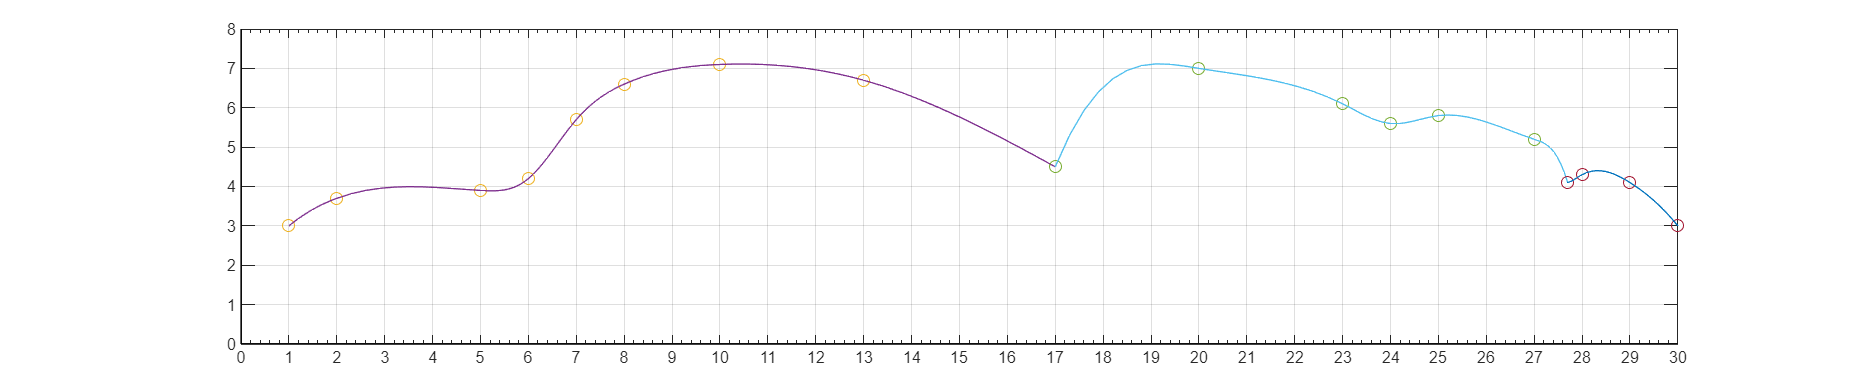

format long
x1=[1,2,5,6,7,8,10,13,17];
y1=[3,3.7,3.9,4.2,5.7,6.6,7.1,6.7,4.5];
v11=[1,-0.67];
x2=[17,20,23,24,25,27,27.7];
y2=[4.5,7.0,6.1,5.6,5.8,5.2,4.1];
v22=[3,-4];
x3=[27.7,28,29,30];
y3=[4.1,4.3,4.1,3.0];
v33=[0.33,-1.5];   %输入点横纵坐标以及端点斜率
plot([0 30],[0,0],'k',[0 0],[0 8],'k');hold on
axis on;%设置坐标轴
set(gca,'fontsize',8,'xminortick','on');
set(gca,'XTick',0:1:30);
set(gcf,'unit','normalized','position',[0,0,0.9,0.3]);
grid on;%设置坐标轴网格
splineplot(x1,y1,v11,10);hold on
splineplot(x2,y2,v22,10);hold on
splineplot(x3,y3,v33,10);%画出钳制三次样条

function coeff=splinecoeff(x,y,v)%计算钳制三次样条系数
%输入：数据点的x,y向量
%     以及两个斜率的向量v
%输出：系数矩阵
n=length(x);
v1=v(1);
vn=v(2);
A=zeros(n,n);%矩阵A是n*n
r=zeros(n,1);
for i=1:n-1%定义delta
    dx(i)=x(i+1)-x(i);dy(i)=y(i+1)-y(i);
end
for i=2:n-1%加载A矩阵
    A(i,i-1:i+1)=[dx(i-1),2*(dx(i-1)+dx(i)),dx(i)];
    r(i)=3*(dy(i)/dx(i)-dy(i-1)/dx(i-1));%右端端点
end
%设置端点条件
A(1,1:2)=[2*dx(1) dx(1)];r(1)=3*(dy(1)/dx(1)-v1);%钳制条件
A(n,n-1:n)=[dx(n-1),2*dx(n-1)];r(n)=3*(vn-dy(n-1)/dx(n-1));
coeff=zeros(n,3);
coeff(:,2)=A\r;%求解系数c
for i=1:n-1%求解b和d
    coeff(i,3)=(coeff(i+1,2)-coeff(i,2))/(3*dx(i));
    coeff(i,1)=dy(i)/dx(i)-dx(i)*(2*coeff(i,2)+coeff(i+1,2))/3;
end
coeff=coeff(1:n-1,1:3);
end

function [x1,y1]=splineplot(x,y,v,k)
%输入：数据点的x,y向量，每段画出的点数k
%     以及两个斜率的向量v
%输出：在画出点上的x1,y1样条值
n=length(x);
coeff=splinecoeff(x,y,v);
x1=[];y1=[];
for i=1:n-1
    xs=linspace(x(i),x(i+1),k+1);
    dx=xs-x(i);
    ys=coeff(i,3)*dx;%使用嵌套算法求值
    ys=(ys+coeff(i,2)).*dx;
    ys=(ys+coeff(i,1)).*dx+y(i);
    x1=[x1;xs(1:k)'];y1=[y1;ys(1:k)'];
end
x1=[x1;x(end)];y1=[y1;y(end)];
plot(x,y,'o',x1,y1)
end